# **session 1: Matrices Algebra**

## Robotics Main Computation

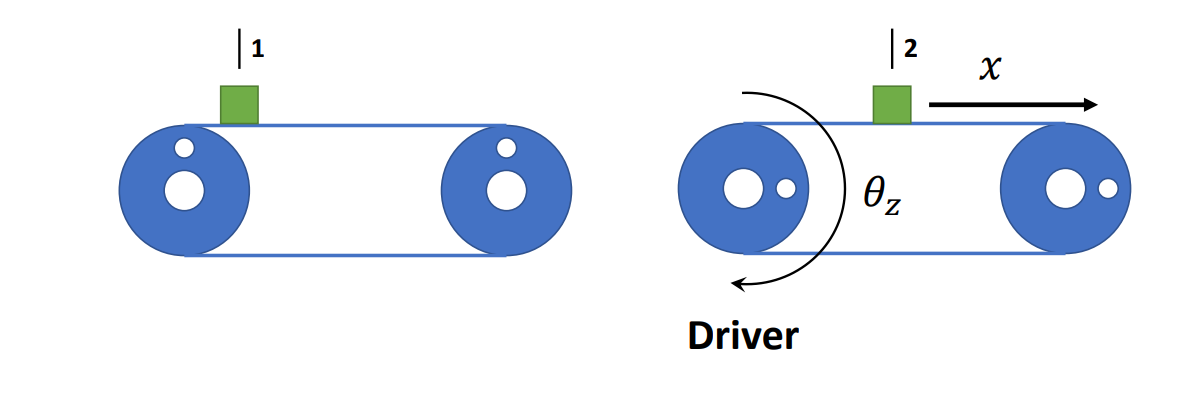

If you move the motor with an angle $\theta_z $, what is the object displacement $X$?

$X(m) = \frac{2\pi R (m)}{360 (deg)}  \theta_z (deg)$  $\Longrightarrow$ **Forward Kinematics**

$\theta_z (deg) = \frac{360 (deg)}{2\pi R(m)}X(m)$  $\Longrightarrow$ **Inverse Kinematics**

### **Forward Kinematics**

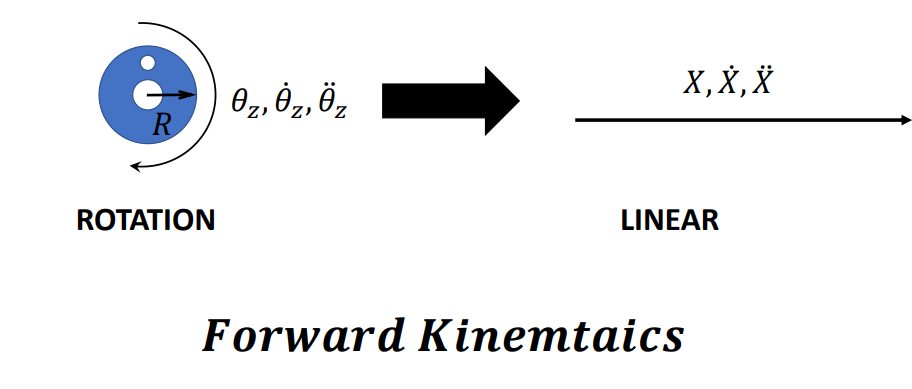

### **Inverse Kinematics**

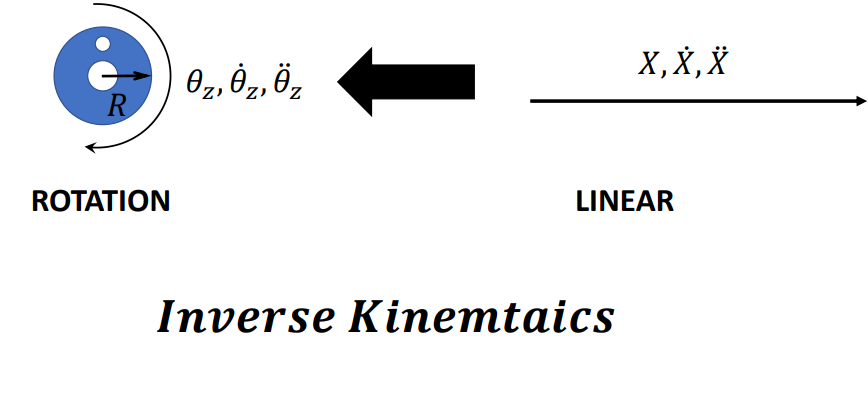

### Forward Dynamics

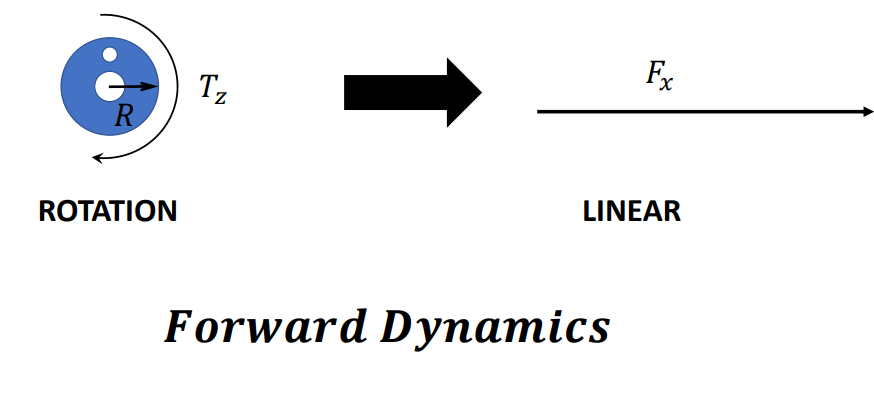

### Inverse Dynamics

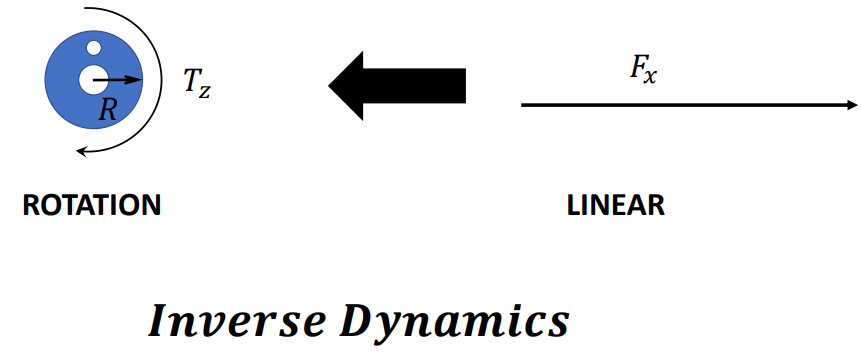

## Matrices 

### Definition

Matrix is a `rectangular` array or table of `numbers`, `symbols`, or `expressions`, with elements or entries arranged in rows and columns, which is used to represent a `mathematical` `object` or property of such an object.

### Problem 

If we had several joints with several degree of freedoms, how would we deal with it?

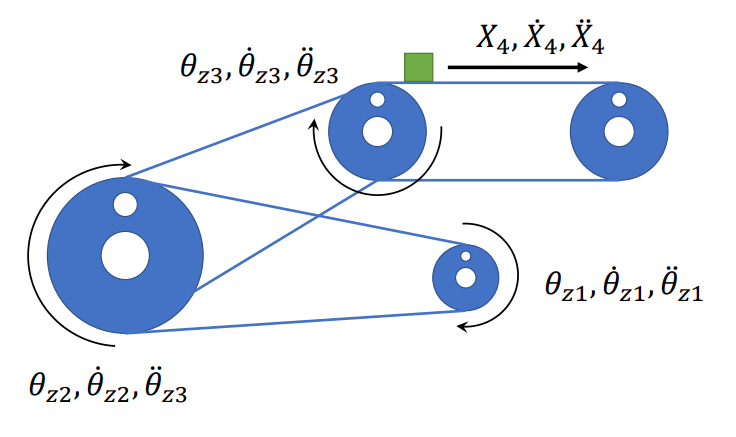

### Objective 

We have to use `matrices` to express those joints. This will be explained in the coming sessions.

## Revision on Matrices Algebra

### Vectors

#### Row Vector

A = [1 2 3 4]

A =      1     2     3     4


or

A = [1, 2, 3, 4]

#### Column Vector

A = [1; 2; 3; 4]

or

A = [1
     2
     3
     4]

### Matrices

#### Rectangular Matrix 

A = [1 2 3 4; 5 6 7 8]

#### Square Matrix

A = [1 2 3; 4 5 6; 7 8 9]

#### Diagonal Matrix 


$$A=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 2 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


d = [1 2 1]
A = diag(d)

#### Identity Matrix  - I


$$A=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


A = eye(3)

#### Null Matrix


$$A=\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$$


A = zeros(3)


$$A=\;\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$$


A = zeros(2,3)

#### Scalar Matrix


$$A=\;\left\lbrack \begin{array}{cccc}
6 & 0 & 0 & 0\\
0 & 6 & 0 & 0\\
0 & 0 & 6 & 0\\
0 & 0 & 0 & 6
\end{array}\right\rbrack$$


c = 6
d = ones(1, 4)
A = diag(d)*c

### **Matrices Operations**

#### Addition


$$\left\lbrack \begin{array}{ccc}
7 & 3 & -1\\
2 & -5 & 6
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
1 & 5 & 6\\
-4 & -2 & 3
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
8 & 8 & 5\\
-2 & -7 & 9
\end{array}\right\rbrack$$


[7 3 -1; 2 -5 6] + [1 5 6; -4 -2 3]

#### Scalar Multiplication


$$A=\left\lbrack \begin{array}{cc}
3 & -1\\
2 & 1\\
2 & -3\\
4 & 1
\end{array}\right\rbrack \;\;\;\;\;k=4$$


A = [3 -1; 2 1; 2 -3; 4 1]
k = 4
A * k

#### Matrices Multiplication


$$A=\left\lbrack \begin{array}{cc}
3 & -1\\
2 & 1\\
2 & -3\\
4 & 1
\end{array}\right\rbrack \;\;\;\;\;\;B=\left\lbrack \begin{array}{ccc}
2 & 3 & 4\\
6 & -1 & 0
\end{array}\right\rbrack$$


A = [3 -1; 2 1; 2 -3; 4 1]
size(A)
B = [2 3 4; 6 -1 0]
size(B)
A * B


$$A=\left\lbrack \begin{array}{cc}
3 & -1\\
2 & 1
\end{array}\right\rbrack \;\;\;\;\;\;I=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$$


A = [3 -1; 2 1]
size(A)
I = eye(2)
size(I)
A * I

#### Matrix Transpose


$$A=\left\lbrack \begin{array}{cc}
3 & -1\\
2 & 1
\end{array}\right\rbrack \;\;\;\;\;\;B=\left\lbrack \begin{array}{cc}
3 & 2\\
-1 & 1
\end{array}\right\rbrack$$


A = [3 -1; 2 1]
B = A'
B = transpose(A)

#### Matrix Inverse 2*2

An invertible matrix must be:

- Square $M_{n \times n}$

- Linearly independent (no column is related to other columns singularity)

- The result of $M_{n\times n}  .  M^{-1} = 1$


$$A=\left\lbrack \begin{array}{cc}
a & b\\
c & d
\end{array}\right\rbrack \;\;\;\;{\;\;\;\;\;\;\;\;A}^{-1} =\frac{1}{\textrm{ad}-\textrm{bc}}\left\lbrack \begin{array}{cc}
d & -b\\
-c & a
\end{array}\right\rbrack$$



$$A=\left\lbrack \begin{array}{cc}
3 & 1\\
2 & 1
\end{array}\right\rbrack {\;\;\;\;\;\;\;\;A}^{-1} =\frac{1}{3-2}\left\lbrack \begin{array}{cc}
1 & -1\\
-2 & 3
\end{array}\right\rbrack =\;$$

$$\left\lbrack \begin{array}{cc}
1 & -1\\
-2 & 3
\end{array}\right\rbrack$$


A = [3 1; 2 1]
inv(A)

### Matrix Inverse 3*3

#### 1. Generate the matrix of minors

 
$$\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
0 & 1 & 4\\
5 & 6 & 0
\end{array}\right\rbrack \Longrightarrow \left\lbrack \begin{array}{ccc}
a &  & \\
 &  & \\
 &  & 
\end{array}\right\rbrack$$
 

$a\;$location is $1\times 1
$, so we would cross out the first column and first row


$$\left\lbrack \begin{array}{ccc}
\cdots  & \cdots  & \cdots \\
\vdots  & 1 & 4\\
\vdots  & 6 & 0
\end{array}\right\rbrack \Longrightarrow a=\left(1\times 0\right)-\left(4\times 6\right)=\;-24$$


 
$$\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
0 & 1 & 4\\
5 & 6 & 0
\end{array}\right\rbrack \Longrightarrow \left\lbrack \begin{array}{ccc}
-24 & b & \\
 &  & \\
 &  & 
\end{array}\right\rbrack$$


 $b\;$location is $1\times 2
$, so we would cross out the first column and first row

 
$$\left\lbrack \begin{array}{ccc}
\cdots  & \cdots  & \cdots \\
0 & \vdots  & 4\\
5 & \vdots  & 0
\end{array}\right\rbrack \Longrightarrow b=\left(0\times 0\right)-\left(4\times 5\right)=\;-20$$


 
$$\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
0 & 1 & 4\\
5 & 6 & 0
\end{array}\right\rbrack \Longrightarrow \left\lbrack \begin{array}{ccc}
-24 & -20 & \\
 &  & \\
 &  & 
\end{array}\right\rbrack$$


 and repeat that till the end

 
$$\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
0 & 1 & 4\\
5 & 6 & 0
\end{array}\right\rbrack \Longrightarrow \left\lbrack \begin{array}{ccc}
-24 & -20 & -5\\
-18 & -15 & -4\\
5 & 4 & 1
\end{array}\right\rbrack$$


#### 2. Generate matrix of cofactors 


$$\left\lbrack \begin{array}{ccc}
-24 & -20 & -5\\
-18 & -15 & -4\\
5 & 4 & 1
\end{array}\right\rbrack$$

$$\Longrightarrow \left\lbrack \begin{array}{ccc}
+ & - & +\\
- & + & -\\
+ & - & +
\end{array}\right\rbrack \Longrightarrow$$

$$\left\lbrack \begin{array}{ccc}
-24 & 20 & -5\\
18 & -15 & 4\\
5 & -4 & 1
\end{array}\right\rbrack$$


#### 3. Find the Adjugate / Adjoint


$$\left\lbrack \begin{array}{ccc}
-24 & 20 & -5\\
18 & -15 & 4\\
5 & -4 & 1
\end{array}\right\rbrack$$
 

We must reflect entries across the main diagonal


$$\left\lbrack \begin{array}{ccc}
\ddots  & 20 & -5\\
18 & \ddots  & 4\\
5 & -4 & \ddots 
\end{array}\right\rbrack \Longrightarrow \left\lbrack \begin{array}{ccc}
\ddots  & 18 & 5\\
20 & \ddots  & -4\\
-5 & 4 & \ddots 
\end{array}\right\rbrack \Longrightarrow \left\lbrack \begin{array}{ccc}
-24 & 18 & 5\\
20 & -15 & -4\\
-5 & 4 & 1
\end{array}\right\rbrack$$
 

#### 4. Divide Adjoint by determinant (original matrix)


$$\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
0 & 1 & 4\\
5 & 6 & 0
\end{array}\right\rbrack =1\left\lbrack \begin{array}{cc}
0 & 4\\
5 & 0
\end{array}\right\rbrack +3\left\lbrack \begin{array}{cc}
0 & 4\\
5 & 0
\end{array}\right\rbrack +3\left\lbrack \begin{array}{cc}
0 & 1\\
5 & 6
\end{array}\right\rbrack =-24+40-15=1$$



$$\frac{1}{1}\left\lbrack \begin{array}{ccc}
-24 & 18 & 5\\
20 & -15 & -4\\
-5 & 4 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
-24 & 18 & 5\\
20 & -15 & -4\\
-5 & 4 & 1
\end{array}\right\rbrack \;$$


#### Magic of Matlab

A = [1 2 3; 0 1 4; 5 6 0]
inv(A)